Create a Demonstration Lane System

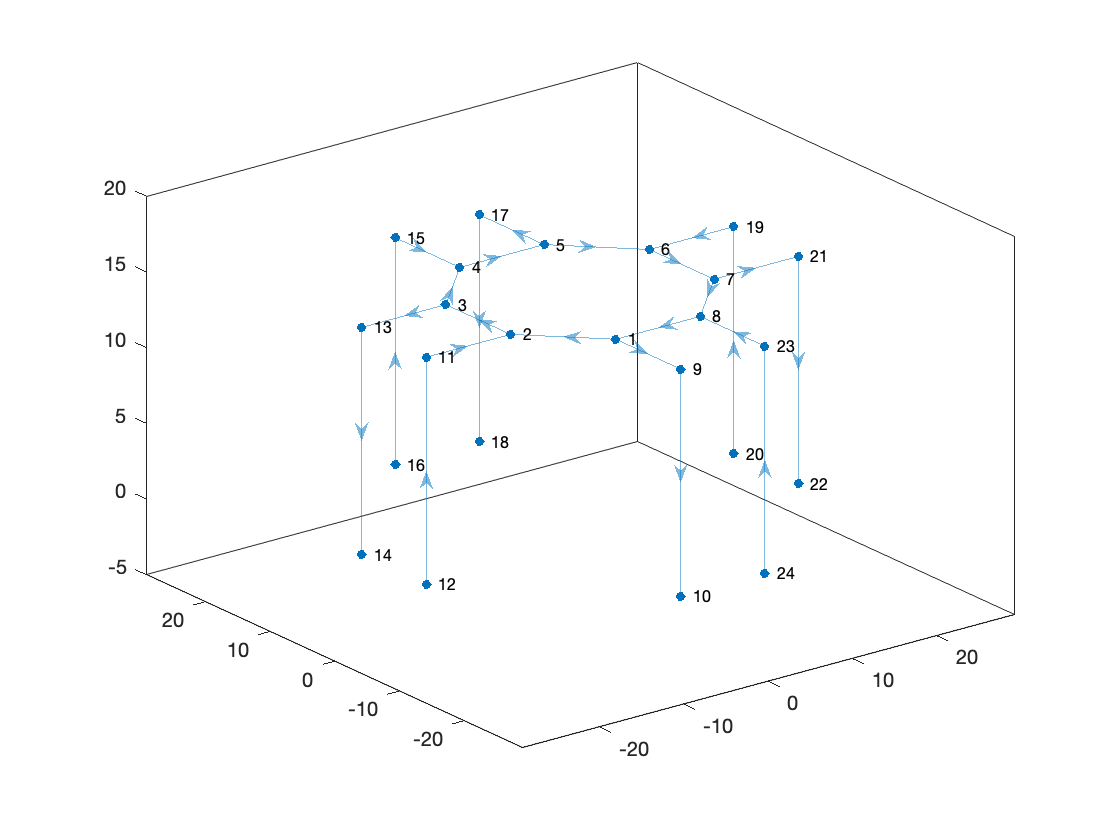

lbsd = LBSD.genSampleLanes(10, 15);

plot(lbsd);

List the lane ids

lane_ids = lbsd.getLaneIds

lane_ids = 24×1 string array
    "2"
    "9"
    "3"
    "4"
    "13"
    "5"
    "6"
    "17"
    "7"
    "8"
    "21"
    "1"
    "10"
    "12"
    "11"
    "14"
    "16"
    "15"
    "18"
    "20"
    "19"
    "22"
    "24"
    "23"


Generate Some Random Reservations:

% genRandReservations(start_time, end_time, num_res, lane_ids)
lbsd.genRandReservations(0, 1000, 1000, ["1","2","5"]);

Get the Reservation Table

lbsd.getReservations

ans = 204×6 table
     id     lane_id    entry_time_s    exit_time_s    speed    hd
    ____    _______    ____________    ___________    _____    __

    "1"       "1"         427.06         429.06         5      10
    "2"       "1"         955.37         957.37         5      10
    "3"       "1"         724.25         726.25         5      10
    "4"       "1"         580.89         582.89         5      10
    "5"       "1"         540.26         542.26         5      10
    "6"       "1"         705.44         707.44         5      10
    "7"       "1"         5.0289         7.0289         5      10
    "8"       "1"         782.52         784.52         5      10
    "9"       "1"         926.86         928.86         5      10
    "10"      "1"         824.63         826.63    

Get the Reservation Table for Specific Lane

lbsd.getLaneReservations("1")

ans = 68×6 table
     id     lane_id    entry_time_s    exit_time_s    speed    hd
    ____    _______    ____________    ___________    _____    __

    "1"       "1"         427.06         429.06         5      10
    "2"       "1"         955.37         957.37         5      10
    "3"       "1"         724.25         726.25         5      10
    "4"       "1"         580.89         582.89         5      10
    "5"       "1"         540.26         542.26         5      10
    "6"       "1"         705.44         707.44         5      10
    "7"       "1"         5.0289         7.0289         5      10
    "8"       "1"         782.52         784.52         5      10
    "9"       "1"         926.86         928.86         5      10
    "10"      "1"         824.63         826.63     

This object also publishes events each time a reservation is made for testing with the ATOC. Here''s a simple example:

Subscribe to events

lbsd.subscribeToNewReservation(@(src,evt)disp("Reservation Made!"));

Then if you run the same experiment as above you'll see something like this:

lbsd.genRandReservations(0, 1000, 1000, ["1","2","5"]);

Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
Reservation Made!
